# **2.3.3 采样及零阶保持**

**一周期信号**$e_1(t)=sin(2\pi t)$**用采样频率 10Hz 进行周期采样，后通过零阶保持 器，试画出：**

**c **通过 ZOH 后输出信号的幅值谱和相位谱。 （**信号经过传递函数；预估一下幅值谱什么样子？**） 

由于傅里叶变换可以表示为：

所以fft导出的幅值如要代表真实幅值则需要/N.又因为导出的幅值包含正负频域的两个分量，所以需要*2.

计算：

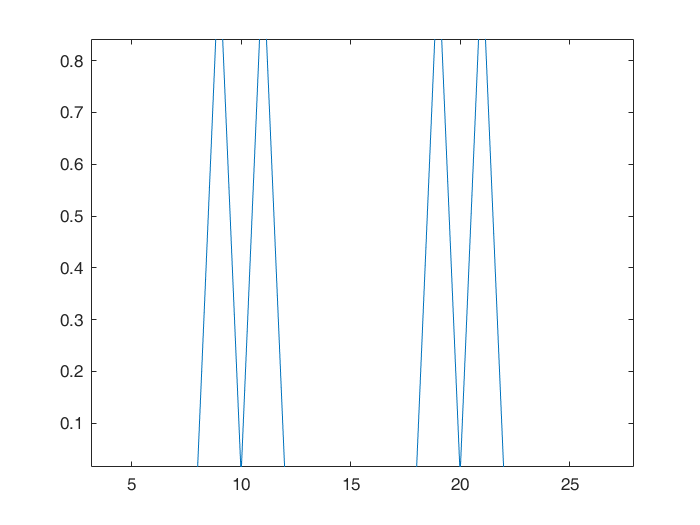

fs = 10; %采样频率为10Hz
t = 0:1/fs:0.9; %采样时间为一个周期
e1 = sin(2*pi*t); %信号
N = size(e1,2); %数据点数 2对应矩阵的列数->10
N3=3*N;
y1 = fft(e1,N); %信号的快速傅里叶变换
f1 = (0:N-1)*fs/N; %频率序列
y3 = [y1,y1,y1]; %周期延拓至0：1：29 乘1/T
mag3 = abs(y3)*2/N;
plot(0:N3-1,mag3);

fs=10;T=1/fs;%采样周期
f3=29;%29Hz

因为傅里叶变换与拉普阿斯区别在于将积分项替换$e^{-j\omega T}=e^{-j2\pi *fs*T}$=>$e^{-sT}$所以计算ZOH的频谱可以将0:1:29Hz 带入

ZOH的传递函数为：$G(s)=\frac{1-e^{-Ts}}{s}$

N3=30;fi3=(0:N3-1).*2*pi;%输入频率序列
yzoh = (1-exp(-T.*1i.*fi3))./(1i.*fi3);%零阶保持器
subplot(3,1,1);
plot(0:N3-1,abs(yzoh))%画出图像

根据书本，经过ZOH输出的信号的拉普拉斯变换为$H_1(s)=\frac{1-e^{-Ts}}{s}\sum_{k=0}^\infty x(kT)e^{-kTs}$，其中没有*Ts

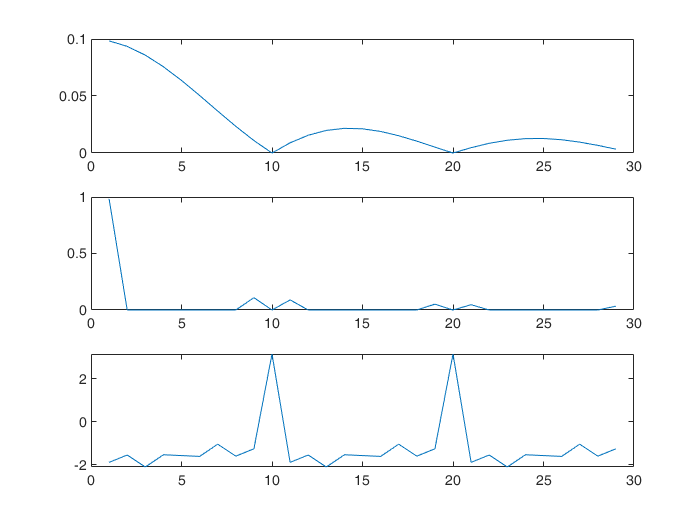

Youtput=yzoh.*y3*2;
subplot(3,1,2);
plot(0:N3-1,abs(Youtput));%幅值谱
subplot(3,1,3);
plot(0:N3-1,angle(Youtput));%相位谱

**d **步骤 **c** 输出信号频谱中前 5 个**非零频率分量**对应的时间信号，并画出 5 个 时间域信号求和后的信号。 在同一张图上画出：采样信号$e_1(kT)=sin(2 \pi kT)、T = 0.1s、k\ge 0$经过零阶 保持器的输出信号（stair 命令），并与前述求和信号进行对比。 

clf;
kNz=find(abs(Youtput)>=0.01&abs(Youtput)<=100);%找到非零元素
kNz5=kNz(1:5)%取前五个序号

kNz5 =      2    10    12    20    22


mag=abs(Youtput(kNz5));%求取前五个信号的幅值
ang=angle(Youtput(kNz5));%求取前五个信号的相位
%绘制5个分量信号

根据$sig_n=Mag_n*cos(2\pi f_n*t+\theta_n)$，绘制前五个幅值所对应的信号分量

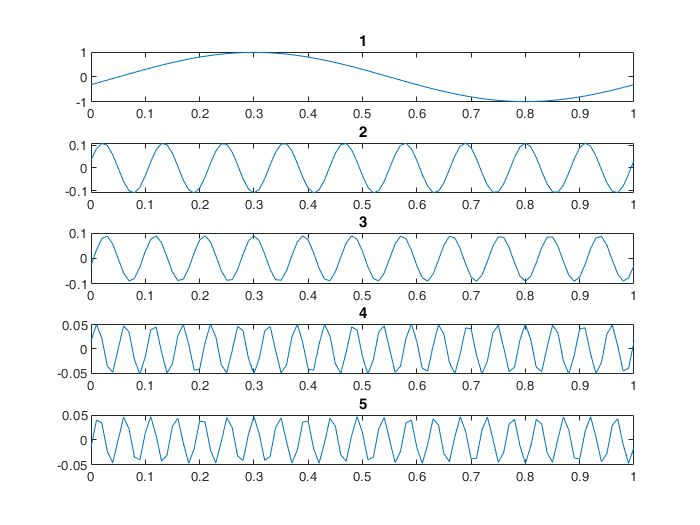

for i=1:5
t=0:1/100:1;
eval(['sig',num2str(i),'=mag(',num2str(i),')*cos(2*pi*(kNz5(',num2str(i),')-1)*t+ang(',num2str(i),'));']);
eval(['subplot(5,1,',num2str(i),');']);
eval(['plot(t,sig',num2str(i),')']);
eval(['title(',num2str(i),');']);
end

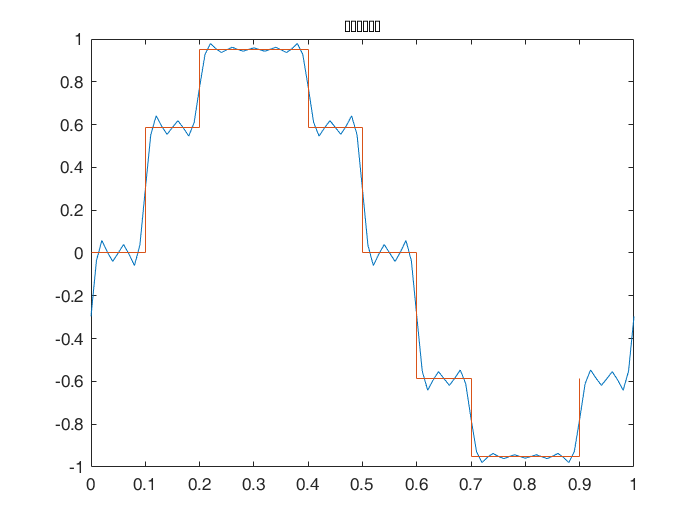

clf;
sig=sig1+sig2+sig3+sig4+sig5;
%求和信号
plot(t,sig)
title("求和后的信号");
hold on;
stairs(0:0.1:0.9,e1);